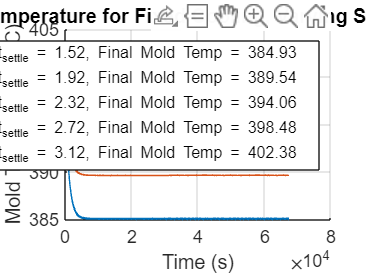

% Load the coefficients from the CSV file
coefficients = readtable('coefficients_exa.csv');

% Initial Conditions and Parameters for Simulation
T_g_initial = 1100;                  % Initial glass gob temperature (fixed)
T_m_initial = 398.6331849779064;     % Initial mold temperature (fixed)
t_cycle = 13.36;                     % Total cycle time (fixed)
cycles_to_sim = 5000;                % Number of cycles to simulate
t_step = 0.08;                       % Time step for simulation (fixed)
T_air = 70;                          % Air temperature (fixed)
t_counter = 1.56;                    % Counter duration

% Surface areas
S_aria = 7.932558e-02;
S_settle = 1.011951e-02;
S_counter = 1.504496e-02;

% Physical constants
C_mold = 1 / (2278.4 * 7300.0 * 2.196412e-03); % Mold heat capacity
C_gob = 1 / (1460.0 * 2350.0 * 9.288814e-05);  % Gob heat capacity

% First Experiment: Fixed cooling, varying settle
experiment1_data = coefficients(1:5, :);  % First 5 rows

% Second Experiment: Fixed settle, varying cooling
experiment2_data = coefficients(6:10, :); % Next 5 rows

% Initialize cell arrays to store results for each scenario
mold_ts_scenarios_exp1 = cell(1, 5);  % For first experiment (fixed cooling)
timestamps_scenarios_exp1 = cell(1, 5);

mold_ts_scenarios_exp2 = cell(1, 5);  % For second experiment (fixed settle)
timestamps_scenarios_exp2 = cell(1, 5);

% First Experiment: Simulate for varying settle times (fixed cooling)
for idx = 1:5
    t_settle = experiment1_data.t_settle(idx);
    t_cooling = experiment1_data.t_cooling(idx);
    
    % Extract the coefficients for each phase
    a1 = [experiment1_data.alfa1_1(idx), experiment1_data.alfa1_2(idx), experiment1_data.alfa1_3(idx), experiment1_data.alfa1_4(idx)];
    a2 = [experiment1_data.alfa2_1(idx), experiment1_data.alfa2_2(idx), experiment1_data.alfa2_3(idx), experiment1_data.alfa2_4(idx)];
    b1 = [experiment1_data.beta1_1(idx), experiment1_data.beta1_2(idx), experiment1_data.beta1_3(idx), experiment1_data.beta1_4(idx)];
    b2 = [experiment1_data.beta2_1(idx), experiment1_data.beta2_2(idx), experiment1_data.beta2_3(idx), experiment1_data.beta2_4(idx)];
    ks = [experiment1_data.k_settle_1(idx), experiment1_data.k_settle_2(idx), experiment1_data.k_settle_3(idx), experiment1_data.k_settle_4(idx)];
    kc = [experiment1_data.k_counter_1(idx), experiment1_data.k_counter_2(idx), experiment1_data.k_counter_3(idx), experiment1_data.k_counter_4(idx)];

    % Initialize the starting times for settle and counter phases
    t_settle_start = 0.0;
    t_counter_start = t_settle_start + t_settle;
    t_cooling_start = 0.0;

    % Simulate multiple cycles
    [gob_ts, mold_ts] = simulate_multiple_cycles(T_g_initial, T_m_initial, ...
        t_settle_start, t_settle, t_counter_start, t_counter, t_cooling_start, t_cooling, ...
        t_cycle, t_step, cycles_to_sim, ...
        a1, a2, b1, b2, ks, kc, S_settle, S_counter, S_aria, C_mold, C_gob, T_air);

    % Store results
    mold_ts_scenarios_exp1{idx} = mold_ts;
    timestamps_scenarios_exp1{idx} = (0:t_step:(length(mold_ts)-1)*t_step)';  % Generate timestamps
end

% Plot the results for mold temperature (First Experiment)
figure(1);
clf;  % Clear the figure before plotting
hold on;
for idx = 1:5
    final_mold_temp = mold_ts_scenarios_exp1{idx}(end);  % Get the final mold temperature
    plot(timestamps_scenarios_exp1{idx}, mold_ts_scenarios_exp1{idx}, ...
         'DisplayName', ['t_{settle} = ', num2str(experiment1_data.t_settle(idx)), ...
         ', Final Mold Temp = ', num2str(final_mold_temp, '%.2f')]);
end
xlabel('Time (s)');
ylabel('Mold Temperature (°C)');
title('Mold Temperature for Fixed Cooling, Varying Settle Times');
legend;
grid on;
hold off;

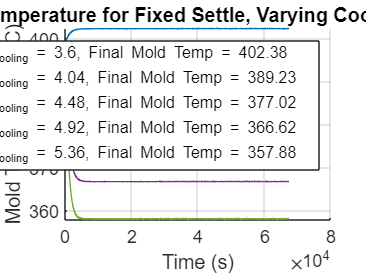


% Second Experiment: Simulate for varying cooling times (fixed settle)
for idx = 1:5
    t_cooling = experiment2_data.t_cooling(idx);
    t_settle = experiment2_data.t_settle(idx);
    
    % Extract the coefficients for each phase
    a1 = [experiment2_data.alfa1_1(idx), experiment2_data.alfa1_2(idx), experiment2_data.alfa1_3(idx), experiment2_data.alfa1_4(idx)];
    a2 = [experiment2_data.alfa2_1(idx), experiment2_data.alfa2_2(idx), experiment2_data.alfa2_3(idx), experiment2_data.alfa2_4(idx)];
    b1 = [experiment2_data.beta1_1(idx), experiment2_data.beta1_2(idx), experiment2_data.beta1_3(idx), experiment2_data.beta1_4(idx)];
    b2 = [experiment2_data.beta2_1(idx), experiment2_data.beta2_2(idx), experiment2_data.beta2_3(idx), experiment2_data.beta2_4(idx)];
    ks = [experiment2_data.k_settle_1(idx), experiment2_data.k_settle_2(idx), experiment2_data.k_settle_3(idx), experiment2_data.k_settle_4(idx)];
    kc = [experiment2_data.k_counter_1(idx), experiment2_data.k_counter_2(idx), experiment2_data.k_counter_3(idx), experiment2_data.k_counter_4(idx)];

    % Initialize the starting times for settle and counter phases
    t_settle_start = 0.0;
    t_counter_start = t_settle_start + t_settle;
    t_cooling_start = 0.0;

    % Simulate multiple cycles
    [gob_ts, mold_ts] = simulate_multiple_cycles(T_g_initial, T_m_initial, ...
        t_settle_start, t_settle, t_counter_start, t_counter, t_cooling_start, t_cooling, ...
        t_cycle, t_step, cycles_to_sim, ...
        a1, a2, b1, b2, ks, kc, S_settle, S_counter, S_aria, C_mold, C_gob, T_air);

    % Store results
    mold_ts_scenarios_exp2{idx} = mold_ts;
    timestamps_scenarios_exp2{idx} = (0:t_step:(length(mold_ts)-1)*t_step)';  % Generate timestamps
end

% Plot the results for mold temperature (Second Experiment)
figure(2);
clf;  % Clear the figure before plotting
hold on;
for idx = 1:5
    final_mold_temp = mold_ts_scenarios_exp2{idx}(end);  % Get the final mold temperature
    plot(timestamps_scenarios_exp2{idx}, mold_ts_scenarios_exp2{idx}, ...
         'DisplayName', ['t_{cooling} = ', num2str(experiment2_data.t_cooling(idx)), ...
         ', Final Mold Temp = ', num2str(final_mold_temp, '%.2f')]);
end
xlabel('Time (s)');
ylabel('Mold Temperature (°C)');
title('Mold Temperature for Fixed Settle, Varying Cooling Times');
legend;
grid on;
hold off;

function [gob_ts, mold_ts] = simulate_multiple_cycles(...
    T_g_initial, T_m_initial, ...
    t_settle_start, t_settle, t_counter_start, t_counter, t_cooling_start, t_cooling, ...
    t_cycle, t_step, cycles_to_sim, ...
    a1, a2, b1, b2, ks, kc, ...
    S_settle, S_counter, S_aria, C_mold, C_gob, T_air)

    % Preallocate storage for all cycles
    steps_per_cycle = ceil(t_cycle / t_step);
    total_steps = steps_per_cycle * cycles_to_sim;
    
    gob_ts_all = zeros(total_steps, 1);
    mold_ts_all = zeros(total_steps, 1);
    
    % Initialize the current mold temperature
    T_mold_current = T_m_initial;
    current_step = 1;

    % Run the simulation for the specified number of cycles
    for cycle = 1:cycles_to_sim
        [gob_cycle, mold_cycle] = simulate_cycle(...
            T_g_initial, T_mold_current, ...
            t_settle_start, t_settle, t_counter_start, t_counter, ...
            t_cooling_start, t_cooling, t_cycle, t_step, ...
            a1, a2, b1, b2, ks, kc, S_settle, S_counter, S_aria, C_mold, C_gob, T_air);
        
        % Store the results for this cycle
        num_steps = length(gob_cycle);
        gob_ts_all(current_step:current_step+num_steps-1) = gob_cycle;
        mold_ts_all(current_step:current_step+num_steps-1) = mold_cycle;
        
        % Update step counter
        current_step = current_step + num_steps;
        
        % Update the mold temperature for the next cycle
        T_mold_current = mold_cycle(end);
    end

    % Trim arrays to actual simulation length
    gob_ts = gob_ts_all(1:current_step-1);
    mold_ts = mold_ts_all(1:current_step-1);
end
% Helper function for polynomial evaluation
function y = apply_cffs(c, x)
    y = c(1) + c(2) * x + c(3) * x^2 + c(4) * x^3;
end


function [gob_ts, mold_ts] = simulate_cycle(...
    T_gob_initial, T_mold_initial, ...
    t_settle_start, t_settle_duration, ...
    t_counter_start, t_counter_duration, ...
    t_cooling_start, t_cooling_duration, ...
    t_cycle, t_step, ...
    a1, a2, b1, b2, ks, kc, ...
    S_settle, S_counter, S_aria, C_mold, C_gob, T_air)

    % Initialize temperatures and times
    T_gob = T_gob_initial;
    T_mold = T_mold_initial;
    time = 0.0;

    gob_ts = T_gob_initial;  % Start with the initial temperature
    mold_ts = T_mold_initial;

    % Loop over the cycle time
    while time < t_cycle
        hf_gob = 0.0;
        hf_cool = 0.0;

        if time >= t_settle_start && time < t_settle_start + t_settle_duration
            [T_gob, T_mold, hf_gob] = simulate_settle(a1, a2, ks, T_gob, T_mold, t_step, S_settle, C_mold, C_gob);
        end

        if time >= t_counter_start && time < t_counter_start + t_counter_duration
            [T_gob, T_mold, hf_counter] = simulate_counter(b1, b2, kc, T_gob, T_mold, t_step, S_counter, C_mold, C_gob);
            hf_gob = hf_counter; % Assuming hf_gob represents the same heat flow in counter phase
        end

        if time >= t_cooling_start && time < t_cooling_start + t_cooling_duration
            [T_mold, hf_cool] = simulate_cooling(T_mold, t_step, S_aria, T_air, C_mold);
        end

        if time >= t_counter_start + t_counter_duration && time < t_cycle
            T_mold = simulate_passive_cooling(T_mold, t_step, T_air, C_mold);
        end

        % Append the scalar values to the arrays
        gob_ts(end+1) = T_gob;       % Append scalar T_gob to gob_ts array
        mold_ts(end+1) = T_mold;     % Append scalar T_mold to mold_ts array

        % Increment time
        time = time + t_step;
    end
end


function [T_g_s, T_m_s, hf_settle] = simulate_settle(a1, a2, ks, T_g, T_m, t_step, S_settle, C_mold, C_gob)
    delta_T = T_g - T_m;
    T_g_surface = apply_cffs(a2, delta_T); % Use apply_cffs for T_g_surface
    T_m_surface = apply_cffs(a1, delta_T); % Use apply_cffs for T_m_surface

    hf_settle = S_settle * apply_cffs(ks, T_g_surface - T_m_surface); % Heat flow during settle

    T_m_s = T_m - (hf_settle * C_mold * t_step); % Update mold temperature
    T_g_s = T_g + (hf_settle * C_gob  * t_step); % Update gob temperature
end

function [T_g_c, T_m_c, hf_counter] = simulate_counter(b1, b2, kc, T_g, T_m, t_step, S_counter, C_mold, C_gob)
    delta_T = T_g - T_m;
    T_g_surface = apply_cffs(b2, delta_T); % Use apply_cffs for T_g_surface
    T_m_surface = apply_cffs(b1, delta_T); % Use apply_cffs for T_m_surface

    hf_counter = S_counter * apply_cffs(kc, T_g_surface - T_m_surface); % Heat flow during counter

    T_m_c = T_m - (hf_counter * C_mold * t_step); % Update mold temperature
    T_g_c = T_g + (hf_counter * C_gob  * t_step); % Update gob temperature
end

function [T_m_c, hf_cooling] = simulate_cooling(T_m, t_step, S_aria, T_air, C_mold)
    hf_cooling = S_aria * 360 * (T_air - T_m); % Cooling heat flow
    T_m_c = T_m + (hf_cooling * C_mold * t_step); % Update mold temperature
end

function [T_m_c] = simulate_passive_cooling(T_m, t_step, T_air, C_mold)
    hf_passive = (T_m - T_air) * 1.053 - 40.99; % Passive cooling heat flow
    T_m_c = T_m - (hf_passive * C_mold * t_step); % Update mold temperature
end